# Parameter Estimation via Profile Likelihoods

## Goals

- **Profile Likelihood and Parameter Estimation:** Provide a quick overview of a parameter estimation approach utilizing profile likelihoods.

- **Water Pumping Network Example: **We used the previously introduced water pumping network to demonstrate the approach's effectiveness. The presented approach estimates unknown parameters with limited and noisy sensor information.

- **Key Enabler: **Demonstrate that surrogate models are key enablers for this approach. 

## High-Level Highlights

Profile likelihood provides a powerful tool to obtain parameter estimates and their confidence intervals. However, this approach tends to be computationally expensive when applied to physics-based models. The workflow becomes feasible by using surrogate models and surrogate model-based optimization. The plot below shows a visualization of our workflow's end product. 

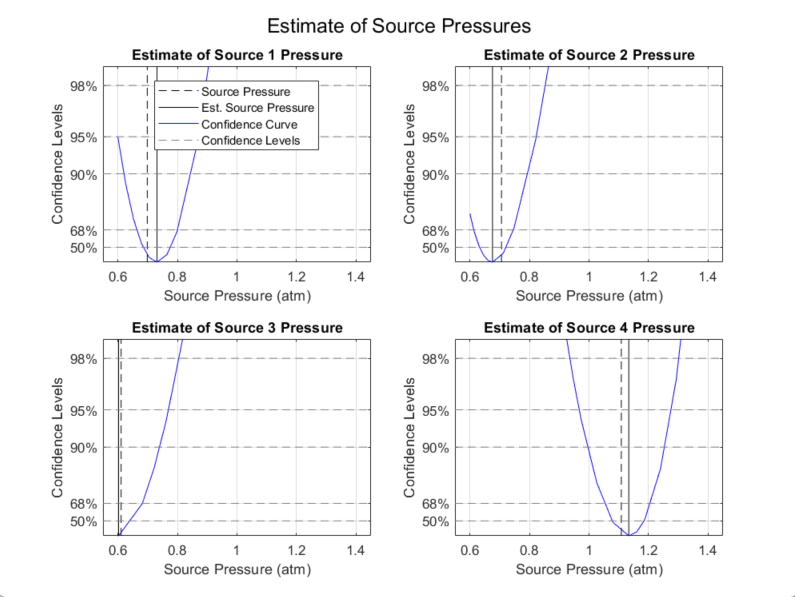

## Profile Likelihood 

Parameter estimation using profile likelihood is a statistical technique employed to infer the values of parameters in a given model. It involves constructing likelihood profiles by maximizing the likelihood function for each parameter of interest while holding a single parameter fixed at specific values. The profile likelihood provides a valuable tool for understanding the relationship between parameters and assessing their uncertainties. The profile likelihood curve offers crucial insights and aids in robust inference and decision-making in various fields such as economics, epidemiology, and physics. A detailed treatment of the topic is given in [1-3].

Constructing a likelihood profile for a single parameter involves repeatedly minimizing (optimizing) an objective. The computational effort of the approach often prevents its use. However, as shown in Model Predictive Operational Point Transition, the computational burden of repeated optimizations is significantly reduced by using a surrogate model. The example below demonstrates that the approach quickly provides parameter estimates with their confidence intervals. Furthermore, parallelization and more efficient surrogate model deployments will make the approach even quicker. 

## Example 

The Basics of Surrogate Model Creation describes the small-scale water pumping network used in the following example. We assume active pressure sensors exist at each line, with a flow rate meter positioned at the collector. Furthermore, sensor readings have additive noise with a normal distribution scaled to a specified variance. The motor speeds and the pressure at the collector (i.e., the system's operational controls) are assumed to be known. Furthermore, the system's operational controls can be varied to place the system into different operational points. Sensor information is collected at different system operational points. In the examples below, random operational points are generated and sampled using the surrogate model.   

Source pressures at all lines are unknown and need to be estimated. Source pressures are assumed to take minimum and maximum values of 0.6 and 1.4 (atm), respectively. 

No sensor information is available for pump powers and line flow rates. However, additional sensor information can be incorporated into the approach if the surrogate model predicts the sensed variable. Furthermore, only inputs to the surrogate model can be estimated. Therefore, the structure of the surrogate determines which sensor information can be used, what parameters can be estimated, and what operational controls can be varied to produce operational points. In summary, inputs to the surrogate need to be known or estimated, and sensor information of all the outputs is not required. The tables below depict the configuration of the parameter estimation workflow, showcasing a single example tailored to this system. We can create a similar configuration to estimate flow rates at individual lines or the total pumping power of the system.

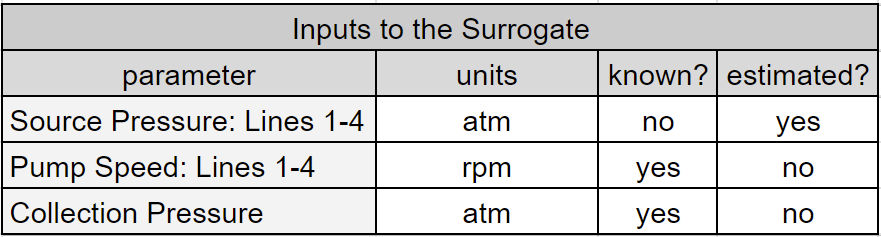

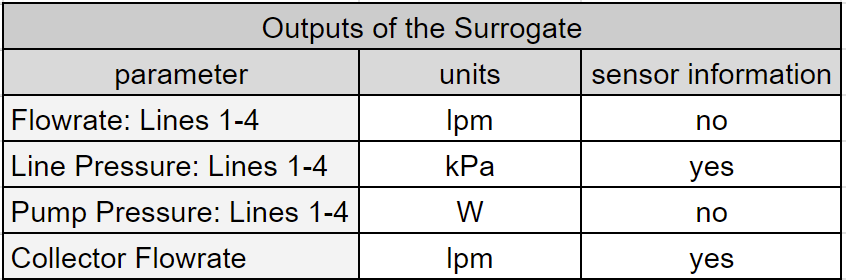

## GUI Interface

The interface below allows the user to:

- Define the number of sensor samples; each sample is taken from an independent operational point

- Select which sensors are active

- Adjust the level of additive noise for each sensor

- Compare results when additional sensor samples are added to the existing sample set

When the execute button is clicked:

- Source pressures are randomly selected (those that will be estimated)

- Random operational points are generated (i.e., motor speeds and collector pressures) 

- The surrogate model is executed at the generated operational points

- Noisey sensor samples are collected from the outputs of the surrogate model

- Parameter estimates of the source pressures and their confidence intervals are generated


numSamples = 10;
disp('Active Sensors:')

Active Sensors:


collector_flowrate = true;
line_1_pressure = true;
line_2_pressure = true;
line_3_pressure = true;
line_4_pressure = true;
disp('Sensor Noise:')

Sensor Noise:


collector_flowrate_sigma = 1.5;
line_1_pressure_sigma = 0.2;
line_2_pressure_sigma = 0.2;
line_3_pressure_sigma = 0.2;
line_4_pressure_sigma = 0.2;

outputIdx = [];
sigma = [];
if collector_flowrate
    outputIdx(end+1) = 1;
    sigma(end+1) = collector_flowrate_sigma;
end
if line_1_pressure
    outputIdx(end+1) = 3;
    sigma(end+1) = line_1_pressure_sigma;
end
if line_2_pressure
    outputIdx(end+1) = 6;
    sigma(end+1) = line_2_pressure_sigma;
end
if line_3_pressure
    outputIdx(end+1) = 9;
    sigma(end+1) = line_3_pressure_sigma;
end
if line_4_pressure
    outputIdx(end+1) = 12;
    sigma(end+1) = line_4_pressure_sigma;
end

 

%% Generate Random Pressures to Estimate
sp = rand(4,1).*[0.8;0.8;0.8;0.8] + [0.6;0.6;0.6;0.6];
source_pressure.source_pressure_1 = sp(1);
source_pressure.source_pressure_2 = sp(2);
source_pressure.source_pressure_3 = sp(3);
source_pressure.source_pressure_4 = sp(4);

disp('Randomly select source pressures:')

Randomly select source pressures:


disp(['Source 1-4 Pressures (atm): ' num2str(source_pressure.source_pressure_1,'%.2f') ', '...
                                    num2str(source_pressure.source_pressure_2,'%.2f') ', '...
                                    num2str(source_pressure.source_pressure_3,'%.2f') ', '...
                                    num2str(source_pressure.source_pressure_4,'%.2f')])

Source 1-4 Pressures (atm): 0.88, 1.17, 0.86, 1.09


Executing parameter estimation...
Generating Profile Curve for Source Pressure 1
Generating Profile Curve for Source Pressure 2
Generating Profile Curve for Source Pressure 3
Generating Profile Curve for Source Pressure 4
A total of 13925 surrogate model evaluations were executed.
Sensor readings from 10 operational points were used in this analysis.


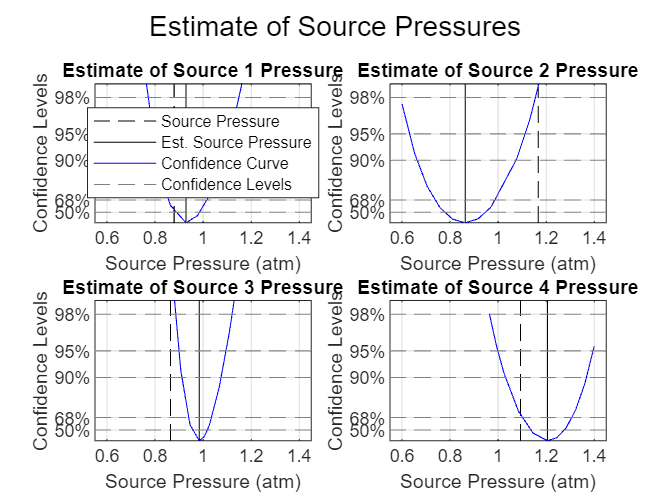

if isempty(outputIdx)
    disp('Select at least one sensor to use.')
else
    addpath("Parameter Estimation\")
    [x] = profileLikelihood(source_pressure,numSamples,[],outputIdx,sigma);
end

numSamples = 5;
disp(['Adding ' num2str(numSamples) '  samples to the existing set.'])

Adding 5  samples to the existing set.


Executing parameter estimation...
Generating Profile Curve for Source Pressure 1
Generating Profile Curve for Source Pressure 2
Generating Profile Curve for Source Pressure 3
Generating Profile Curve for Source Pressure 4
A total of 13554 surrogate model evaluations were executed.
Sensor readings from 25 operational points were used in this analysis.


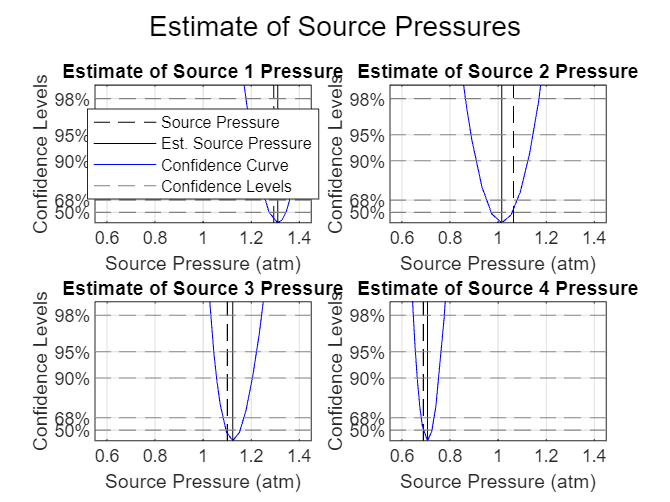

 
addpath("Parameter Estimation\")
[x] = profileLikelihood(source_pressure,numSamples,x,outputIdx,sigma);

## Scenarios

This section explores various scenarios to illustrate how algorithmic inputs impact confidence bounds qualitatively. Source pressures and operating conditions are randomly chosen for each scenario; therefore, the reader should not compare different scenarios quantitatively. 

### Scenario #1: Baseline

This initial scenario serves as a baseline for comparison with others. We utilize ten sensor samples from the collector flow meter and line pressure sensors. We assume an additive noise model for the flow meter and pressure sensors of $$\mathcal{N}(0,1.5^2)$$ (lpm) and $$\mathcal{N}(0,0.2^2)$$ (kPa), respectiviely. The plot below shows the computed estimates and their confidence intervals. 

#### Computational Cost

For this scenario, 15,766 surrogate model evaluations were executed. As noted in Model Predictive Operational Point Transition, substituting the surrogate model with a physics-based one would render this approach infeasible due to the substantial computational effort required. This disparity would only escalate with larger and more intricate systems. A comparison table outlines the computational effort necessary for an equivalent number of physics-based evaluations, highlighting the crucial role played by the surrogate model in facilitating this workflow.

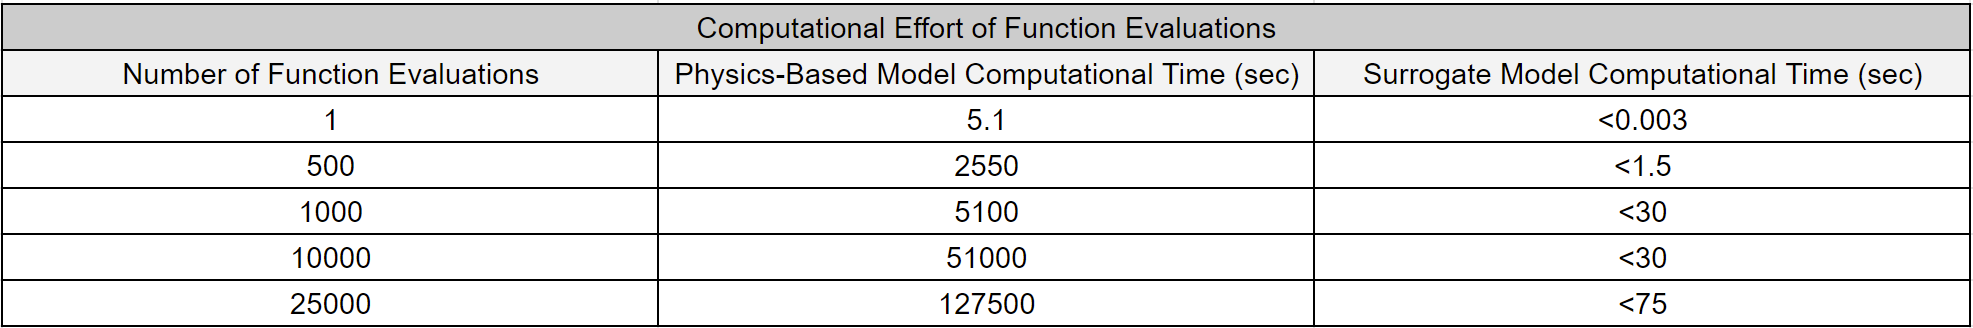

### Scenario #2: Additional Sensor Samples

We add ten sensor samples with the same noise characteristics to the existing sensor information in the baseline scenario. The new data results in narrower confidence curves, enhancing confidence in the estimated parameters. 

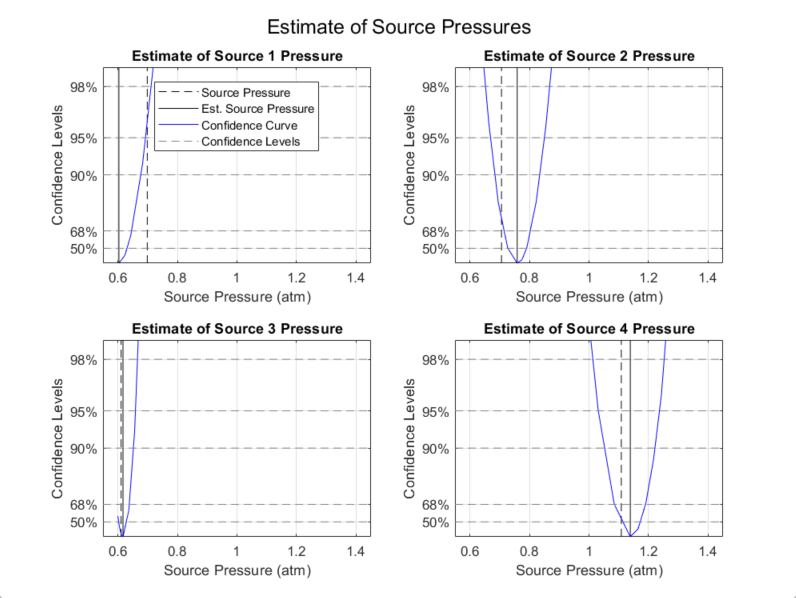

### Scenario #3: Low Noise

In this scenario, we reduce the noise levels across all sensors. Ten sensor samples are gathered, with noise models for the flow meter and pressure sensors specified as $$\mathcal{N}(0,0.25^2)$$ (lpm) and $$\mathcal{N}(0,0.1
^2)$$ (kPa), respectiviely. The resulting parameter estimation and profile curves exhibit significantly narrower confidence bounds compared to the baseline scenario, reflecting the heightened level of certainty resulting from reduced sensor noise.

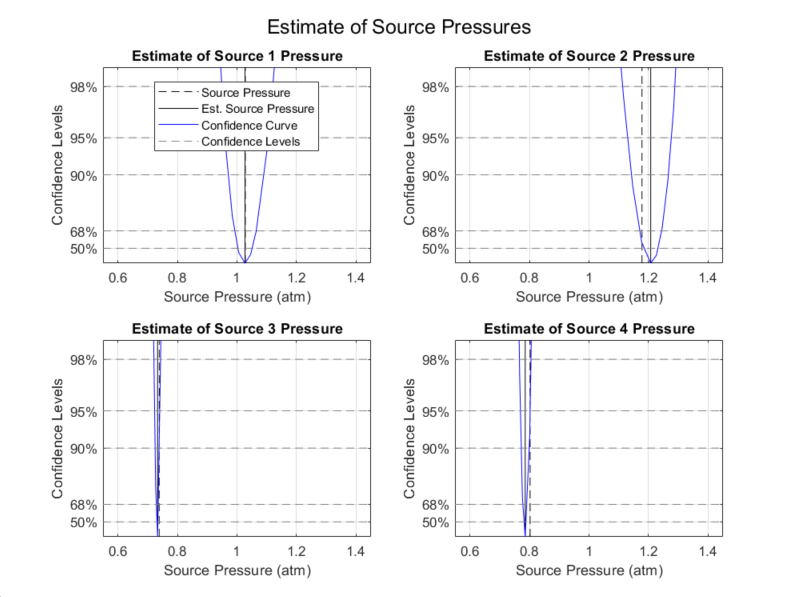

### Scenario #4: No Pressure Sensors

In this setup, we exclude pressure sensors and rely solely on the flow rate sensor with a noise model of $$\mathcal{N}(0,1.5^2)$$ (lpm). With less useful information available, the confidence bounds expand compared to the baseline scenario. The resulting parameter estimates exhibit lower confidence levels than those in the baseline scenario. 

This approach facilitates the comparison of sensor placements and selections, empowering system designers to devise more effective designs.

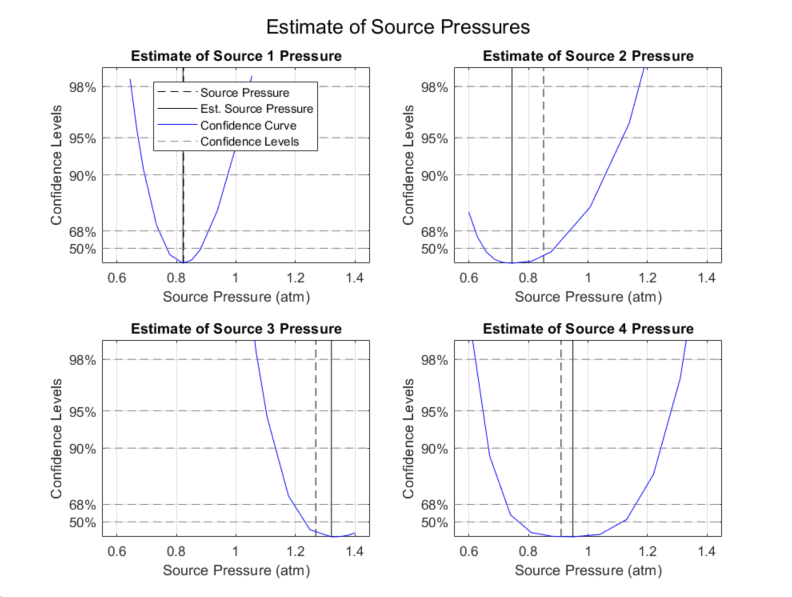

## Summary

We demonstrated an approach for parameter estimation with confidence intervals. While effective and insightful, this approach can be computationally demanding. However, we illustrated that utilizing a surrogate model renders the approach feasible. As in Model Predictive Operational Point Transition, surrogate models are the methodology's key enabler. 

## References

- [Raue, Andreas, et al. "Structural and practical identifiability analysis of partially observed dynamical models by exploiting the profile likelihood." *Bioinformatics* 25.15 (2009): 1923-1929.](https://academic.oup.com/bioinformatics/article/25/15/1923/213246)

- [Kreutz, Clemens. *Statistical Approaches for Molecular and Systems Biology*. Diss. Verlag nicht ermittelbar, 2011.](https://freidok.uni-freiburg.de/fedora/objects/freidok:8404/datastreams/FILE1/content)

- [Kreutz, Clemens, Andreas Raue, and Jens Timmer. "Likelihood based observability analysis and confidence intervals for predictions of dynamic models." *BMC Systems Biology* 6 (2012): 1-9.](https://bmcsystbiol.biomedcentral.com/articles/10.1186/1752-0509-6-120)